# Create Differential Expression Containers

**Author**: Scott Campit

## Summary

This notebook creates the `DE` structure that will be used to constrain the metabolic model in the `EMT_COBRA_Models.mlx` notebook.

clear all

## Load datasets

This code block loads the pre-mapped expression datasets into MATLAB for processing. Note that the data has been pre-processed in R.

We also need to load the RECON1 metabolic model to ensure that we're capturing metabolic genes only.

load ~/Data/Reconstructions/RECON1/recon1.mat
entrez_ids = recon1.geneEntrezID;

Let's also set up some parameters that will be held constant in this analysis

params.standardization = 'log2';
params.filter = entrez_ids;
params.thresh = 0;
params.alpha = 0.05;

### GSE17708 (Keshamouni)

GSE17708 contains time points from $t_{0\textrm{hrs}}$ to $t_{72\textrm{hrs}}$ after $\textrm{TGF}\beta$ treatment.

First, we''ll load up the data

filepath       = '~/Data/Expression/RNASeq/GSE17708/processed/GSE17708_processed.xlsx';
df             = readcell(filepath);
tmp            = cell2mat(df(2:end, 4:end));

Next, specify the `data` structure and the `params` field `name` for the `DEA` function.

data.control   = tmp(:, 1);
data.treatment = tmp(:, 2:end);
data.id        = string(df(2:end, 2));
params.name    = "GSE17708";

Finally, we can run the custom function DEA.mlx in the dea repo. Further documentation is in the [livescript](https://github.com/ScottCampit/dea/blob/master/src/MATLAB/DEA.mlx), but the processing steps are described below:

GSE17708       = DEA(data, params);

### GSE17518 (Thannickal)

GSE18518 contains two time points after $\textrm{TGF}\beta$ treatment.

filepath       = '~/Data/Expression/RNASeq/GSE17518/GSE17518_processed.xlsx';
df             = readcell(filepath);
tmp            = cell2mat(df(2:end, 4:end));
data.control   = tmp(:, 1);
data.treatment = tmp(:, 2:end);
data.id        = string(df(2:end, 2));
params.name    = "GSE17518";
GSE17518       = DEA(data, params);

### Garcia Proteomics

This proteomics dataset from Garcia and colleagues contains several time points from $t_{0\textrm{hrs}}$ to $t_{48\textrm{hrs}}$ after $\textrm{TGF}\beta$ treatment. Because the data was preprocessed in a slightly different way, I'll manually perform DEP in the code block below.

First load the data

filepath       = '~/Data/Expression/Proteomics/Garcia/processed/processed_garcia.xlsx';
df             = readcell(filepath);

% Solve some formatting errors
tmp            = df(2:end, 3:end);
tmp            = string(tmp);
tmp            = str2double(tmp);

params.name    = "Garcia";

Let's get the IDs

id = string(df(2:end, 2));

There are two controls: one for 5 minutes and 1 hr, then one for 24hrs and 48hrs. We need to parse these out to compute the fold change.

tmp1 = tmp(:, [3, 4]) ./ tmp(:, 1);
tmp2 = tmp(:, [5, 6]) ./ tmp(:, 2);
fc = [tmp1, tmp2];

clear tmp1 tmp2

Compute log2 fold change

effectSize = log2(fc);

We need to do some data imputation

effectSize(isnan(effectSize)) = 0;
effectSize(effectSize > 0 & isinf(effectSize)) = max(effectSize(isfinite(effectSize)));
effectSize(effectSize < 0 & isinf(effectSize)) = min(effectSize(isfinite(effectSize)));
pvalue = normpdf(effectSize);

clear fc

Get metabolic data only.

[~, ia]    = intersect(id, params.filter);
id         = id(ia, :);
effectSize = effectSize(ia, :);
pvalue     = pvalue(ia, :);

clear ia

Get the rest of the data and save into the structure

for j = 1:size(effectSize, 2)
    Garcia{j}.name            = params.name;
    Garcia{j}.standardization = params.standardization;
    Garcia{j}.up              = id(effectSize(:, j) > params.thresh & ...
                               pvalue(:, j) <= params.alpha);
    Garcia{j}.down            = id(effectSize(:, j) < -params.thresh & ...
                               pvalue(:, j) <= params.alpha);
end    
clear effectSize pvalue

### Keshamouni Proteomics

This proteomics dataset from Keshamouni et al., contains two time points $t_{0\textrm{hrs}}$ and $t_{72\textrm{hrs}}$ after $\textrm{TGF}\beta$ treatment.

filepath       = '~/Data/Expression/Proteomics/Keshamouni/processed_keshamouni.xlsx';
df             = readcell(filepath);

tmp            = cell2mat(df(2:end, 4:end));

data.control   = tmp(:, 1);
data.treatment = tmp(:, 2:end);
data.id        = string(df(2:end, 2));

params.name    = "Keshamouni";
Keshamouni     = DEA(data, params);

## Format DE containers

This code block creates a `DE` structure that will contain all Entrez ID mapped differentially expressed genes.

DE = {GSE17708, GSE17518, Garcia, Keshamouni};

Save the data as a file to reference later.

filename = "~/Data/Expression/Combined/EMT_DE_struct.mat";
save(filename, "DE");

## Extract differentially expressed genes/proteins from original datasets

This code block extracts differentially expressed genes and proteins using the statistical tests determined in their respective papers. This was done for GSE17708 and the Garcia proteomics data. 

However, GSE17518 doesn't have up- and downregulated genes, and the Keshamouni et al., 2019 proteomics data only has the IPI protein identifiers that are up- and downregulated. So, I will perform DEG/DEP for these datasets. 

### Extract GSE17708 DEGs

Let's load the data and set non-signficiant fold changes to be `NaN`.

savefilepath = '~/Analysis/EMT/DE.mat';

% Load GSE17708
filename = '~/Data/RNASeq/GSE17708/GSE17708_Keshamouni_TGFB1_logs.xls';
log2fc   = readcell(filename, "Sheet", "SigFC");

% Get the gene identifiers
identifiers = log2fc(6:end, 1:5);

% Get intersection
[~, ia, ib] = intersect(string(entrez_ids), string(identifiers(:, 4)));
identifiers = identifiers(ib, :);

% Get the numeric data
data     = cell2mat(log2fc(6:end, 6:end));
data(data == 1) = NaN;

We'll use the median value as the threshold for upregulation and downregulation, as they did not specify how genes were classified in the original manuscript.

thresh = nanmedian(data);

thresh =     2.3847    2.5163    2.4134    2.3874    2.2764    2.1092    2.0895    2.0460


Get metabolic genes from the GSE17708 dataset that are differentially expressed.

% Get metabolic gene DEGs
data        = data(ib, :);
identifiers(all(isnan(data), 2), :) = [];
data(all(isnan(data), 2), :) = [];

Construct the GSE17708 MATLAB structure. The Entrez IDs are stored this in the DE cell array.

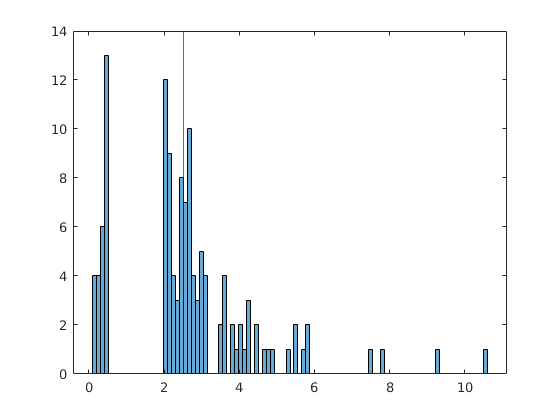

for i = 1:size(data, 2)
    GSE17708{i}.up   = identifiers(data(:, i) > thresh(i), 4); 
    GSE17708{i}.down = identifiers(data(:, i) < thresh(i), 4);
end

% Store results in DE array
DE{1} = GSE17708;
save(savefilepath, "DE");

### Extract Lu et al 2019 DEP

filename = "~/Data/Proteomics/Garcia/raw/DEP_EMT.xlsx";
log2fc   = readcell(filename, "Sheet", "Log2FC");
pvalue   = readcell(filename, "Sheet", "PValue");

pvalue = 3033×15 cell array
    {'Majority Protein ID'}    {'Majority Protein name'                                               }    {'Majority Gene name'}    {'Protein IDs'}    {'Protein names'                                                                                                                            }    {'Gene names'}    {'Peptide counts'}    {'Sequence coverage [%]'}    {'Mol. weight [kDa]'}    {'Sequence length'}    {'Score'    }    {'-Log2 (t-test p-value)'}    {1×1 missing  }    {1×1 missing  }    {1×1 missing   }
    {1×1 missing          }    {1×1 missing                                                           }    {1×1 missing         }    {1×1 missing  }    {1×1 missing                                                                                                                                }    {1×1 missing }    {1×1 missing     }    {1×1 missing            }    {1×1 missing        }    {1×1 missing      }    {1×1 missing}    {'5 min/0 min'           

log2fc = string(log2fc(3:end, 12:end));
mask = ismissing(log2fc);
log2fc(mask) = NaN;

pvalue = string(pvalue(3:end, 12:end));
mask = ismissing(pvalue);
pvalue(mask) = NaN;

log2fc = str2double(log2fc);
pvalue = str2double(pvalue);

log2fc(pvalue > 0.05) = NaN;

for i = 1:size(log2fc, 2)
    Garcia{i}.up   = identifiers(data(:, i) > thresh(i), 4); 
    Garcia{i}.down = identifiers(data(:, i) < thresh(i), 4);
end

## Conclusions

We constructed a `DE` structure that contains `up` and `down` fields containing identifiers that can be mapped to RECON1 for the iMAT algorithm. 

**Next steps:**

- The `DE` structure needs to be applied to the `EMT_COBRA_Models.mlx` script in order to get gene and reaction KO data. 

- The DEG/DEP heatmap needs to be visualized to identify commonalities across all datasets, if there are any. 